[s,fs]=audioread('test_16k.wav');
duration=400;
ham=hamming(duration);
voiced_speech=s(13000:1:13400-1);
unvoiced_speech=s(3400:1:3800-1);
windowed_voiced_speech=(voiced_speech.*ham)';
windowed_unvoiced_speech=(unvoiced_speech.*ham)';

%log magnitude spectrum
magnitude_spectrum_voice=fftshift(fft(windowed_voiced_speech,duration));
magnitude_spectrum_unvoice=fftshift(fft(windowed_unvoiced_speech,duration));

%real cepstrum
[ccepstrum_voice,rcepstrum_voice]=Cepstrum(windowed_voiced_speech,duration);
[ccepstrum_unvoice,rcepstrum_unvoice]=Cepstrum(windowed_unvoiced_speech,duration);

%low quefrency liftered log magnitude spectrum
voiced_low=ifftshift(ccepstrum_voice);
voiced_low(51:349)=0;
voiced_low(50)=0.5*voiced_low(50);
voiced_low(350)=0.5*voiced_low(350);
voiced_low_liftered=fftshift(fft(voiced_low,duration));
unvoiced_low=ifftshift(ccepstrum_unvoice);
unvoiced_low(51:349)=0;
unvoiced_low(50)=0.5*unvoiced_low(50);
unvoiced_low(350)=0.5*unvoiced_low(350);
unvoiced_low_liftered=fftshift(fft(unvoiced_low,duration));



figure
subplot(4,1,1);
plot(13000:13400-1,windowed_voiced_speech);
title('voiced section using hamming window');
subplot(4,1,2);
plot((-duration/2:(duration-1)/2)/duration*fs,log(abs(magnitude_spectrum_voice)));
title('voiced log magnitude spectrum');
subplot(4,1,3);
plot(-duration/2:(duration-1)/2,rcepstrum_voice);
title('voiced real cepstrum');
subplot(4,1,4);
plot((-duration/2:(duration-1)/2)/duration*fs,voiced_low_liftered);

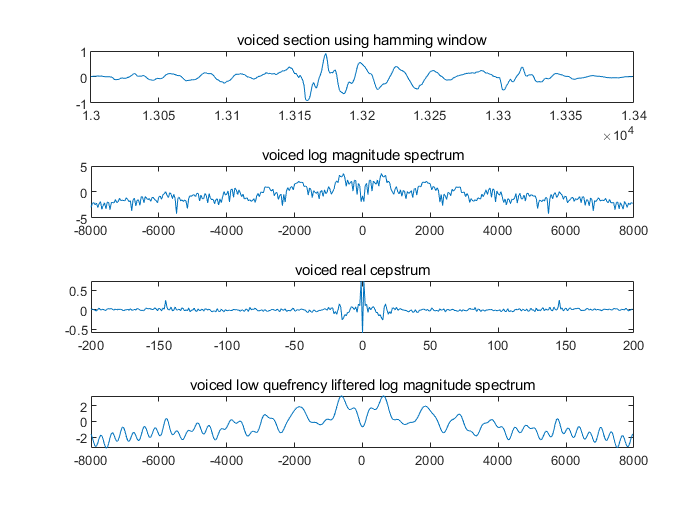

title('voiced low quefrency liftered log magnitude spectrum');

figure
subplot(4,1,1);
plot(3400:3800-1,windowed_unvoiced_speech);
title('unvoiced section using hamming window');
subplot(4,1,2);
plot((-duration/2:(duration-1)/2)/duration*fs,log(abs(magnitude_spectrum_unvoice)));
title('unvoiced log magnitude spectrum');
subplot(4,1,3);
plot(-duration/2:(duration-1)/2,rcepstrum_unvoice);
title('unvoiced real cepstrum');
subplot(4,1,4);
plot((-duration/2:(duration-1)/2)/duration*fs,unvoiced_low_liftered);

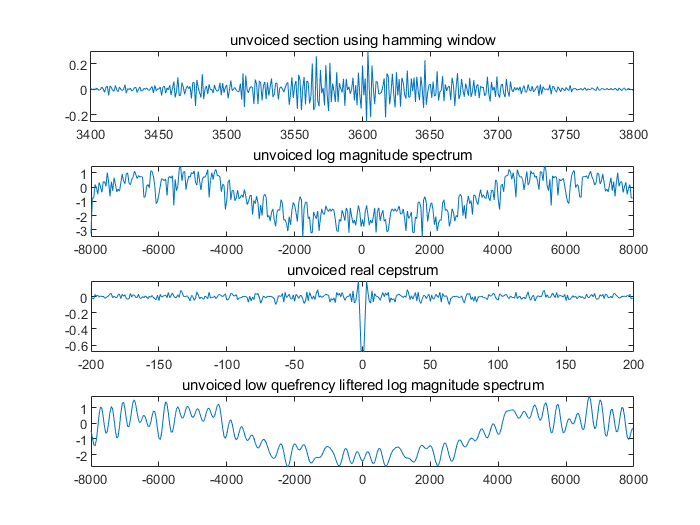

title('unvoiced low quefrency liftered log magnitude spectrum');